# EEE3548 Exercise #4 CT Image Formation (Forward) model & Reconstruction (Backproj) 

## [23.05.16] [ImHyeonJeong]

#### Q1. Generate your own radon transformation using imrorate(). Use built-in radon() to compare your results. Comment on the efficiency of your own radon transformation. Set the number of the anglular samples to 257.

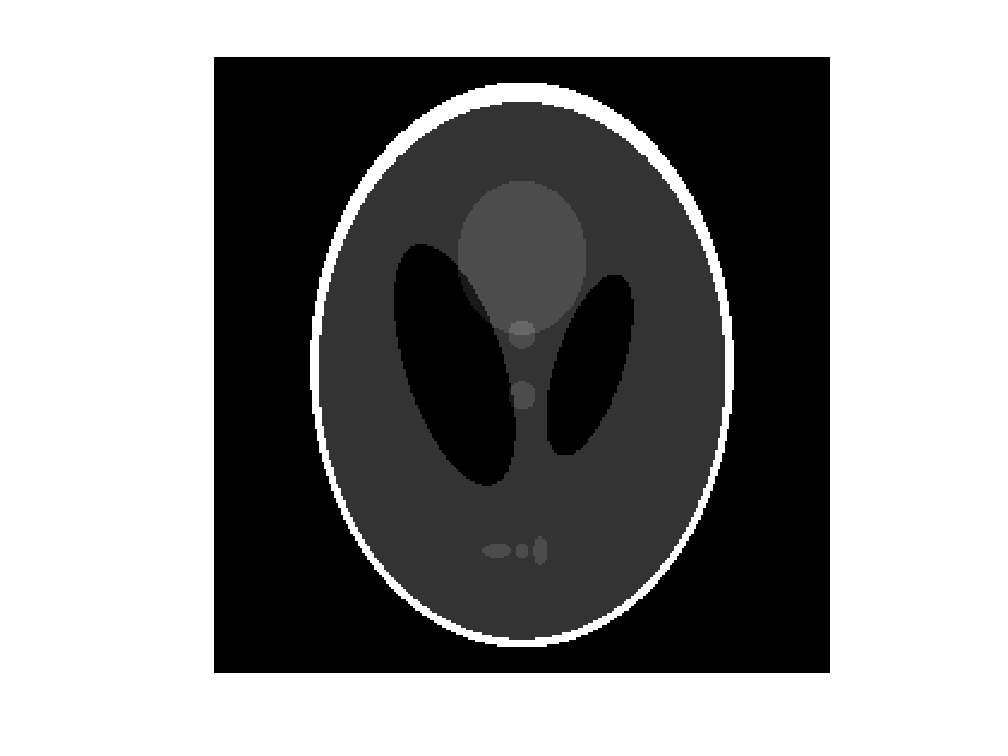

clc;
clearvars;

% use built-in phantom image
obj = phantom(257);
thetas = linspace(0, 180, 257);
dt = 1;

imagesc(obj); colormap gray; axis image; axis off;

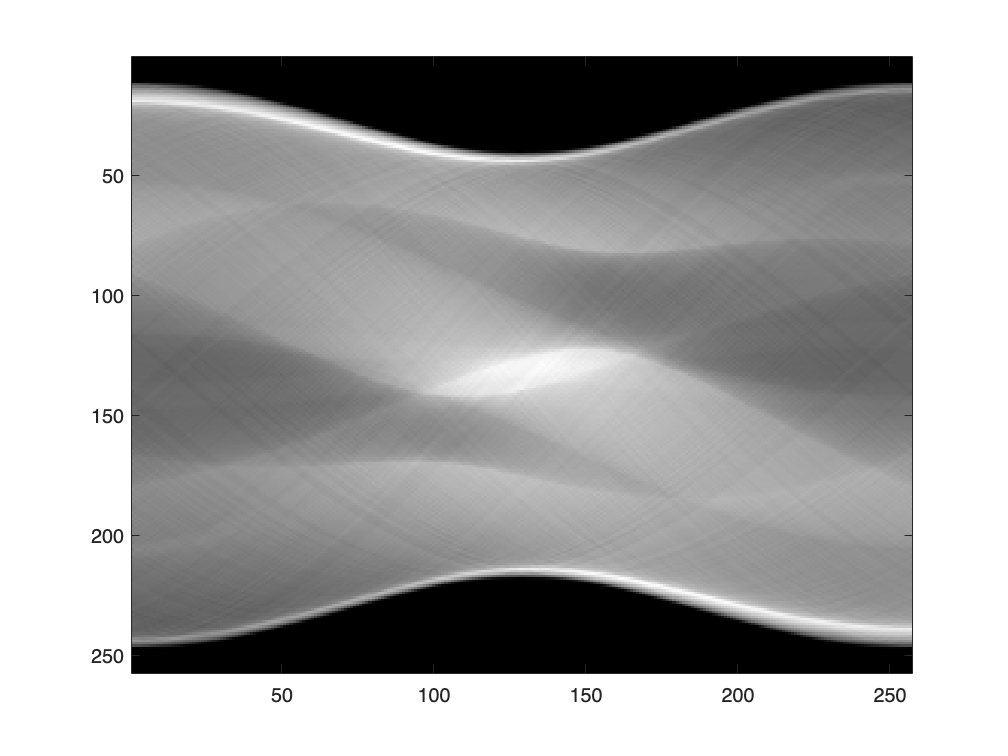

% radon transformation using imrotate()
for i = 1 : dt: length(thetas)
    tmpImage = imrotate(obj, -thetas(i), 'bilinear', 'crop'); % rotation of img
    sinogram(:, i) = sum(tmpImage, 2); % summation

end
figure; imagesc(sinogram); colormap gray;

#### Q2. From the sinogram, generate a single backprjection image at $\theta$ = 30 deg. Use imrotate function.

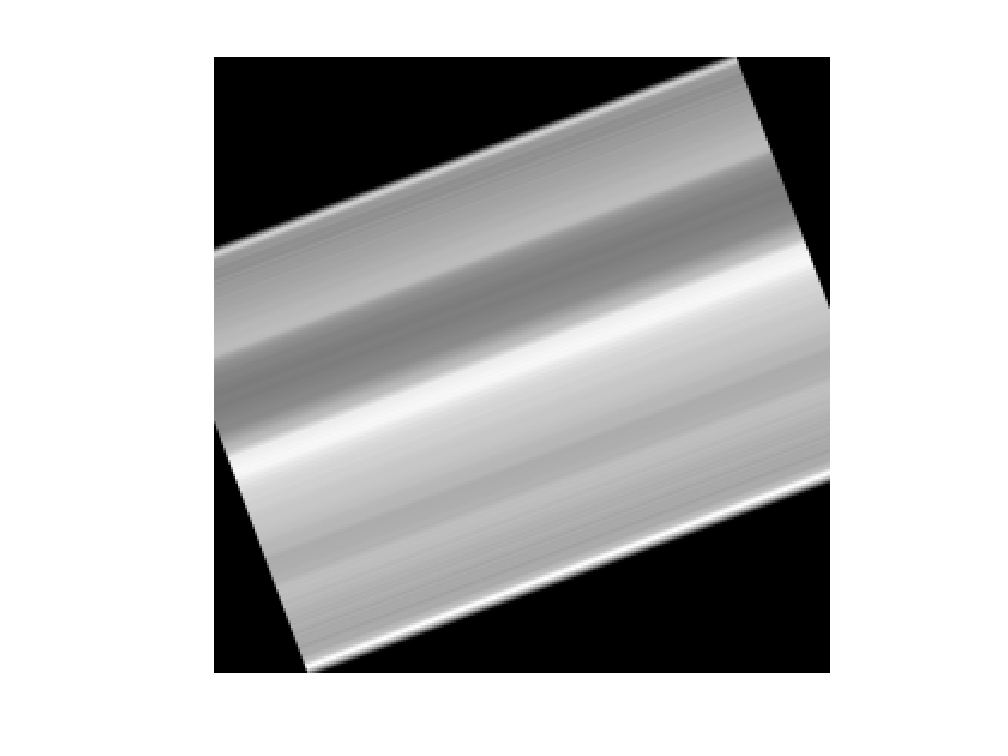

[row, col] = size(sinogram); 
backproj = zeros(size(sinogram));

for i = 1 : dt : length(thetas)
    backproj = backproj + imrotate(repmat(sinogram(:,i), [1,col]), thetas(i), 'bilinear', 'crop');
end

% sinogram(:,i) : 세로로 sinogram 한줄 취해오면 1D array
% repmat : 1D array를 가로(col)로 256개만큼 반복 -> 2D matrix
% imrotate : 0도로 쭉 반복시킨 것을 thetas(i) 각도만큼 회전

% single backprjection image at  = 30 deg
figure; imagesc(imrotate(repmat(sinogram(:,150), [1,col]), thetas(30), 'bilinear', 'crop')); colormap gray; axis image; axis off;

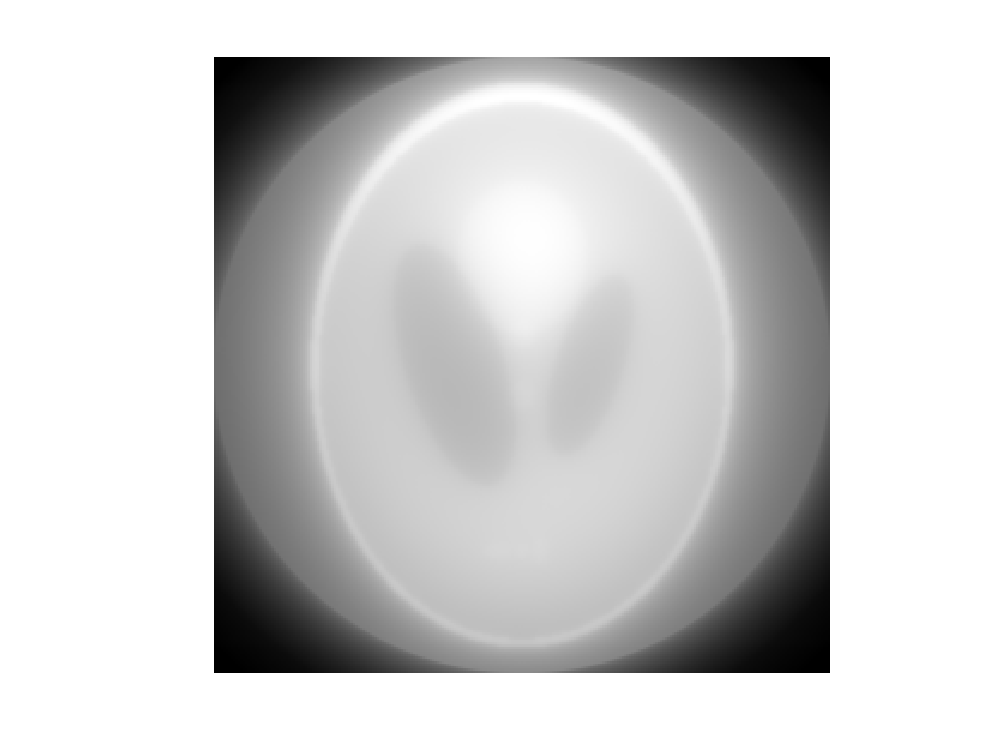

% reconstructed image by backprojection method
figure; imagesc(backproj); colormap gray; axis image; axis off;

#### Q3. Implement the Fourier method backprojection. From the sinograms, fill in the Fourier spectrum of the object according to the central slice theorem, and then take an inverse Fourier transform to get the reconstructed image.

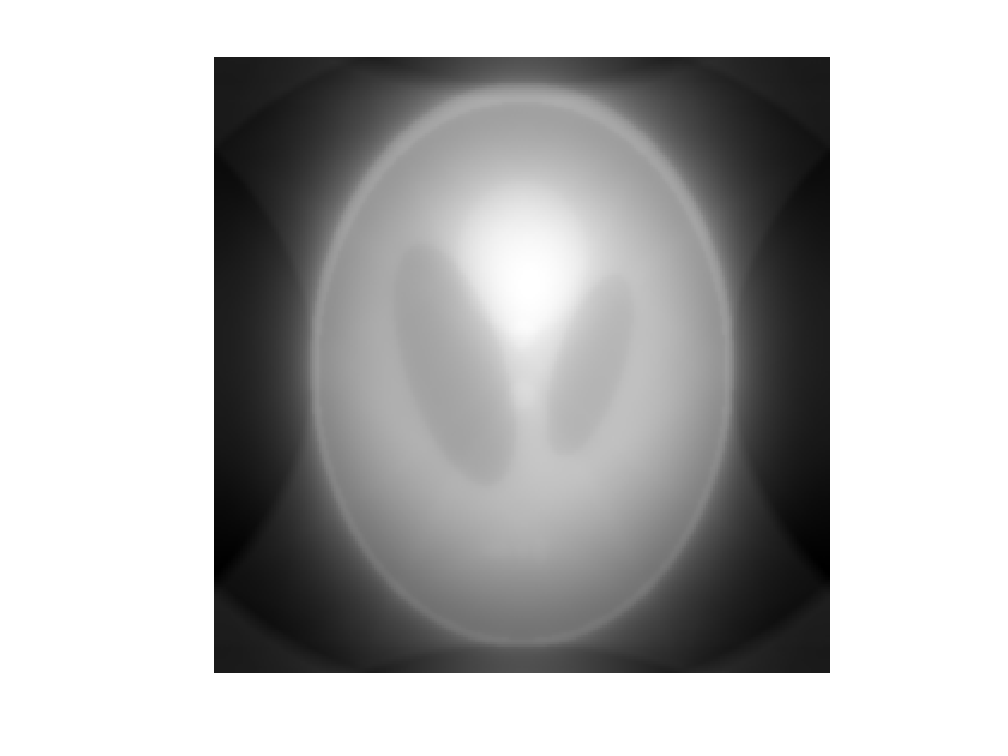

digDim = length(thetas);
ft_obj = zeros(digDim);

for i = 1 : dt : length(thetas)
    signal = fftshift(fft(ifftshift(sinogram(:,i)))); % 1d vector

    f_obj = zeros(size(sinogram));
    f_obj(:, round(digDim/2)) = signal;

    ft_obj = ft_obj + imrotate(f_obj, thetas(i),'bilinear','crop');
end

F_backproj = fftshift(ifft2(ifftshift(ft_obj)));

figure; imagesc(real(F_backproj)); colormap gray; axis image; axis off;

#### Q4. Filter each projection with a ramp filter and implement the filtered backprojection algorithm. (Hint: Use the real part of the filtered projection.) 

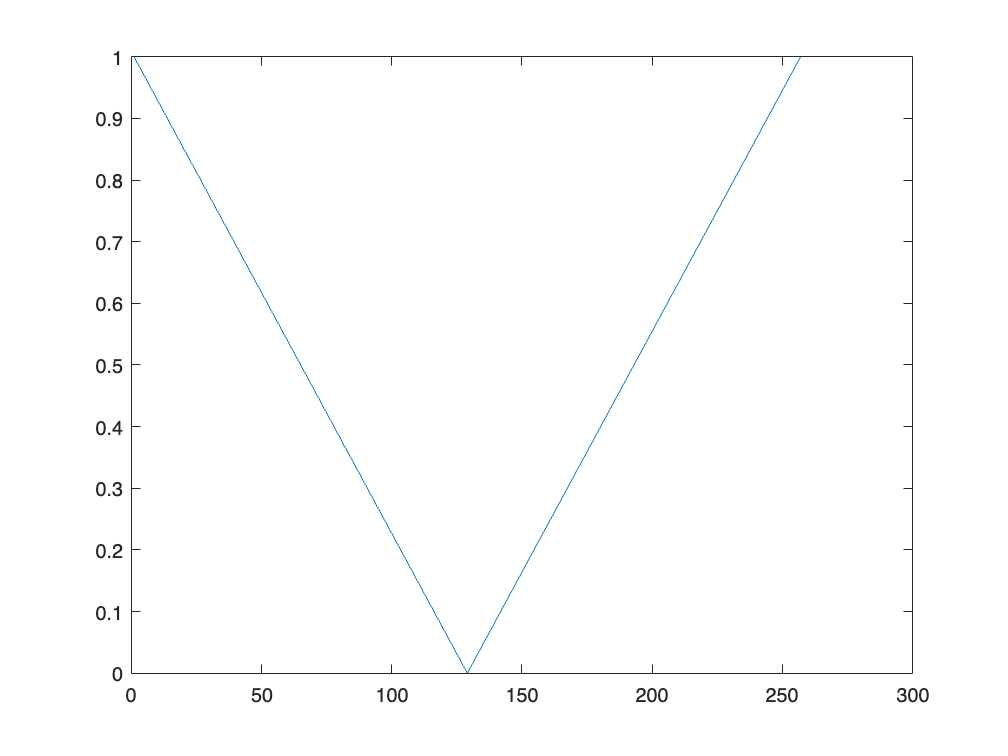

% Ramp Filter
RampFilter = abs(linspace(-1, 1, 257).');
plot(RampFilter)

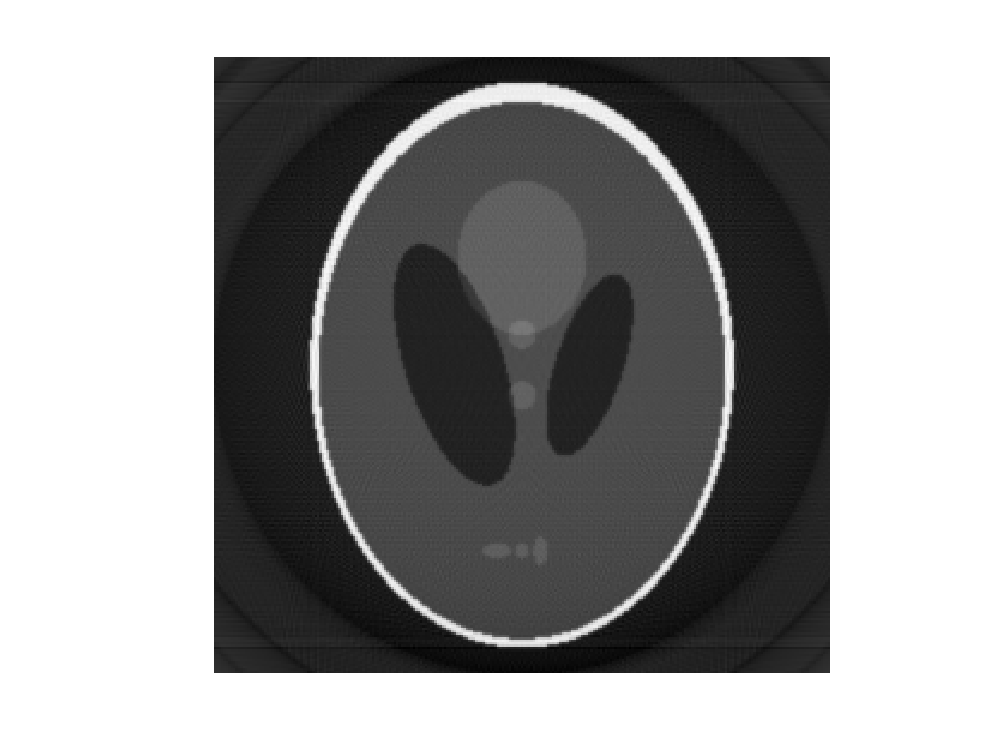

[row, col] = size(sinogram); 
filter_backproj = zeros(size(sinogram));

for i = 1 : dt : length(thetas)
    ft_sinogram = fftshift(fft(sinogram));
    filteredProj = ft_sinogram .* RampFilter;
    filteredProj = ifft(ifftshift(filteredProj));
    filter_backproj = filter_backproj + imrotate(repmat(filteredProj(:,i), [1,col]), thetas(i), 'bilinear', 'crop');
end

figure; imagesc(real(filter_backproj)); colormap gray; axis image; axis off;

#### Q5. Implement the Filtered Fourier method backprojection with ramp filter. 

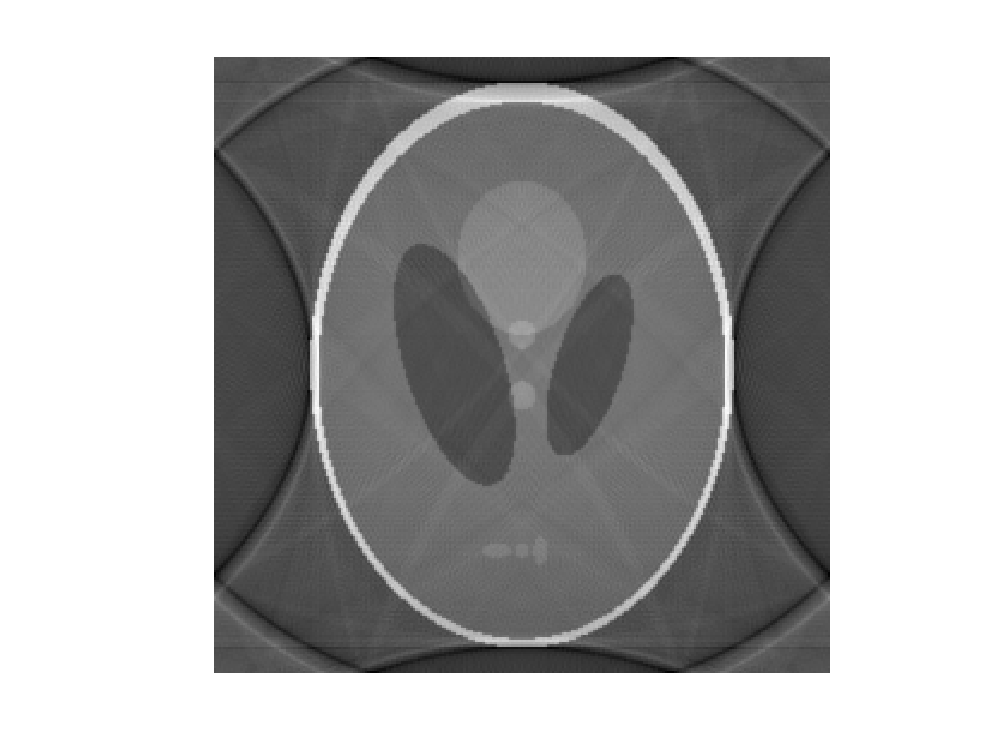

% 3번 line에 ramp filtering 추가
digDim = length(thetas);
ft_obj = zeros(digDim);

for i = 1 : dt : length(thetas)
    signal = fftshift(fft(ifftshift(sinogram(:,i)))); % 1d vector

    f_obj = zeros(size(sinogram));
    f_obj(:, round(digDim/2)) = signal;

    ffilteredProj = f_obj .* RampFilter; % ramp filtering
    
    ft_obj = ft_obj + imrotate(ffilteredProj, thetas(i),'bilinear','crop');
end

FF_backproj = fftshift(ifft2(ifftshift(ft_obj)));

figure; imagesc(real(FF_backproj)); colormap gray; axis image; axis off;

### Discussion

이번 Exercise에서는 CT image formation (forward) model을 만들고 여러 reconstruction 방법을 구현하여 결과를 비교해보았다. 

먼저, **forward model**을 만들기 위해 하나의 slice에서 l 방향으로 scanning을 하고 θ 방향으로 rotation을 하는 과정을 식으로 표현하여 radon transformation을 구현했다. 즉, f(x,y)를 특정한 방향의 line에 대해서 그 line에 해당하는 픽셀들만 취해서 한 방향으로 더하는 과정을 모든 θ에 대해 진행하여 g(l, θ)를 생성했고 결과적으로는 sinogram 형태를 확인할 수 있었다. 

Reconstruction 방법으로는 Backprojection method, Fourier method, Filtered backprojection method, Filtered Fourier back projection method를  사용해보았다.

**Backprojection method**는 가장 간단하지만 원본과 비교했을 때 완벽하지는 않은 복원 방법이다. Radon transformation sinogram g(l, θ)에서 하나의 세로 line을 가져와서 그 line을 가로로 쭉 반복해 2d matrix를 만들고 θ만큼 회전하는 과정을 모든 θ에 대해 진행해 더함으로써 이미지를 reconstruction 하였다. 그러나, 원본에 비해 blurry한 특성이 강하게 나타나는 것이 확인되었다. 

**Fourier method**는 Projection slice therom에 기반하여 이론적으로는 완벽하지만 실제로 구현해보면 원본과 좀 다른 결과가 나타나는 방법이다. Projection slice therom은 sinogram g(l, θ)의 한 line을 1D FT한 결과가 f(x, y)의 2D FT의 특정 방향 성분과 같다는 일종의 FT property이다. g(l, θ)의 한 line을 취해서 l 방향으로 1D FT를 취하고 kx, ky를 채워 좌표를 재배치해주는 과정을 모든 θ에 대해 진행한 후 2D IFT를 취해 recontruction 하는 과정을 거치게 된다. 그러나 실제 구현 과정에서 k space를 plot 해보면 안쪽의 low frequency 영역은 많이 채워지지만 바깥쪽의 high frequency 영역은 잘 채워지지 않기에 복원이 제대로 이루어지지 않는 것을 확인할 수 있다. 따라서 복원 결과를 보면 low pass filter를 통과한 것 같은 이미지를 얻게 된다. 

**Filtered backprojection method**는 수식적으로 완벽한 reconstruction 방법이다. 2D FT를 rect coordinate가 아닌 polar coordinate 상에서 진행하는 것이다. 코드 상에서는 기존 Backprojection 과정에 ramp filtering을 추가함으로써 구현할 수 있으며, 위에서 구현한 다른 방법들에 비해 원본 대비 복원 결과가 훨씬 선명하고 좋았다. 

마지막으로는 Fourier method 중간에 ramp filtering 과정을 추가한 **Filtered backprojection method**을 구현해보았다. Fourier method를 사용하면 그 결과로 나오는 신호가 low frequency 부분에 비교적 몰리게 되는데 ramp high pass filter를 통과시키면 이러한 현상이 좀 완화되어 더 복원이 잘 될 것 같다는 생각이 들었다. 또한, 외곽 부분에서 추가적인 곡선들이 생긴 것을 확인할 수 있었는데 이는 sampling 과정과 interpolation 과정에서 오차가 발생해 추가적인 artifact가 발생한 것으로 예상된다. 이는 dt 값을 줄여 좀 더 세밀한 sampling을 진행하거나 interpolation 방법을 변경하여 완화할 수 있을 것이다.